cd('/lampllab/Data/Awake_AP2.5_ML4.0_A1/FVB/270721/849/WhiskingSound')

data = load_open_ephys_binary([exp_path,'/experiment1/recording1/structure.oebin'],'continuous',1,'mmap');
aud_data = data.Data.Data.mapped(32 + mic,:)

aud_data = 1×53851648 int16 row vector
   309   321   303   351   341   295   297   320   317   298   313   337   329   323   403   379   373   293   275   291   350   357   351   391   399   375   337   303   305   297   333   381   387   323   321   363   341   323   295   353   306   233   269   328   325   297   305   321   319   307


spl = importdata('non_audibleSPL.txt');
sou = audioread('non_audible.wav')

sou =    -0.0032
   -0.0014
    0.0010
    0.0051
   -0.0069
    0.0026
    0.0052
   -0.0050
    0.0047
    0.0013


aud_data_start = 23564914;
aud_end_data = 25442440;

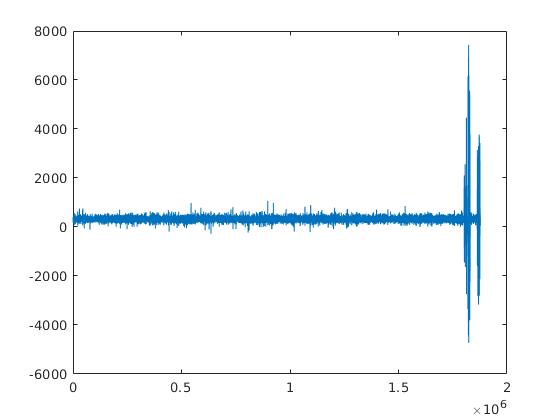

figure; plot(aud_data(aud_data_start:aud_end_data))

aud_al = aud_data(aud_data_start:aud_end_data);

aud_al = normalize(aud_al,'range',[-1,1]);
aud_al = aud_al-mean(aud_al);

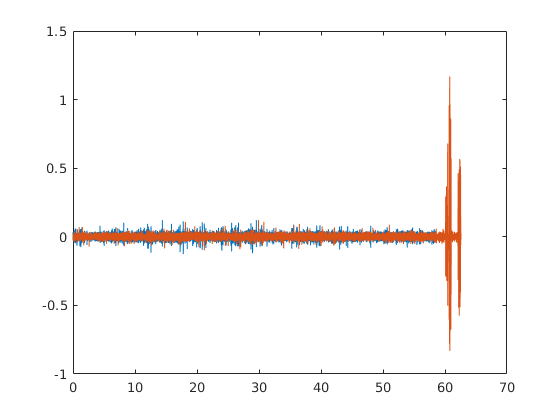

figure;
plot([1:length(sou)]/250000,sou)
hold on
plot([1:length(aud_al)]/30000,aud_al)

aud_al = aud_al(10502:end)

aud_al =    -0.0015    0.0044   -0.0030   -0.0059   -0.0044   -0.0015    0.0021   -0.0028    0.0025    0.0056    0.0041    0.0023    0.0057   -0.0038   -0.0023   -0.0071   -0.0087   -0.0041   -0.0071   -0.0061   -0.0002    0.0059    0.0064    0.0044    0.0011    0.0015   -0.0089    0.0018   -0.0002   -0.0015   -0.0094   -0.0003    0.0043    0.0025    0.0026    0.0034    0.0038   -0.0054   -0.0061   -0.0015    0.0028    0.0044   -0.0054   -0.0074    0.0038    0.0076    0.0051   -0.0015   -0.0082   -0.0018


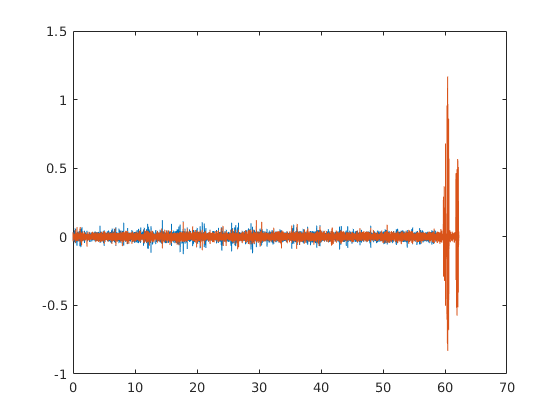

figure;
plot([1:length(sou)]/250000,sou)
hold on
plot([1:length(aud_al)]/30000,aud_al)

section_length = floor((aud_end_data-aud_data_start)/30000)

section_length = 61

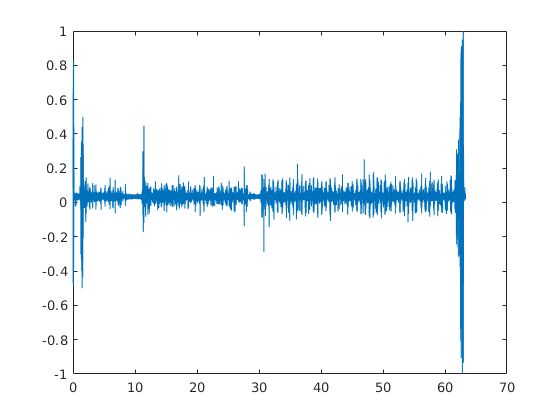

figure; plot([1:length(aud_al)]/30000,aud_al)

hold on
plot([1:length(sou)]/250000,sou)

diff_times = 0.3501

diff_times = 0.3501

diff_ep = 10502

diff_ep = 10502

aud_data_start = aud_data_start+32454;

[~,start_whisk] = min(abs(experiment.Cams.whsiking.csv_aligned_frames - aud_data_start))
%section_length = end_section-start_section
end_whisking = floor(start_whisk + section_length*400)

whisk_section = normalize(motion(start_whisk:end_whisking),'range',[0,1]);

start_whisk = 313632

whisk_section = smoothdata(whisk_section,"gaussian",50);

end_whisking = 338032

[~,start_spl] =  min(abs(spl(:,1) - start_section))
[~,end_spl] =  min(abs(spl(:,1) - end_section))
new_spl = spl(start_spl:end_spl,:);
new_spl(:,1) = new_spl(:,1) - start_section;

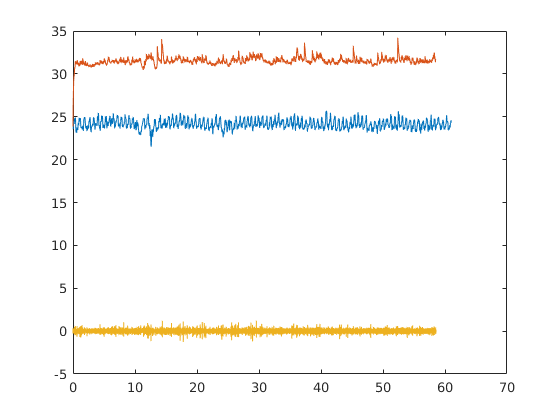

figure;
plot([1:length(whisk_section)]/400,(whisk_section*10)+20)
hold on
plot(spl(:,1),spl(:,2))
plot([1:length(sou)]/250000,sou*10)

NonAudible_whisking_sound.sound = sou;
NonAudible_whisking_sound.spl = spl;
NonAudible_whisking_sound.whisk = whisk_section;

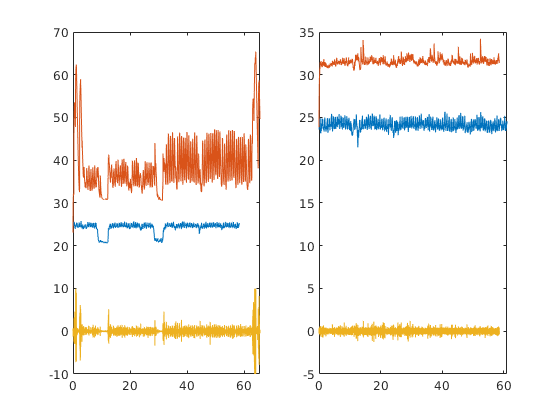

figure;
subplot(1,2,1)
plot([1:length(Audible_whisking_sound.whisk)]/400,(Audible_whisking_sound.whisk*10)+20)
hold on
plot(Audible_whisking_sound.spl(:,1),Audible_whisking_sound.spl(:,2))
plot([1:length(Audible_whisking_sound.sound)]/250000,Audible_whisking_sound.sound*10)
subplot(1,2,2)
plot([1:length(NonAudible_whisking_sound.whisk)]/400,(NonAudible_whisking_sound.whisk*10)+20)
hold on
plot(NonAudible_whisking_sound.spl(:,1),NonAudible_whisking_sound.spl(:,2))
plot([1:length(NonAudible_whisking_sound.sound)]/250000,NonAudible_whisking_sound.sound*10)